概率论基础各种分布演示

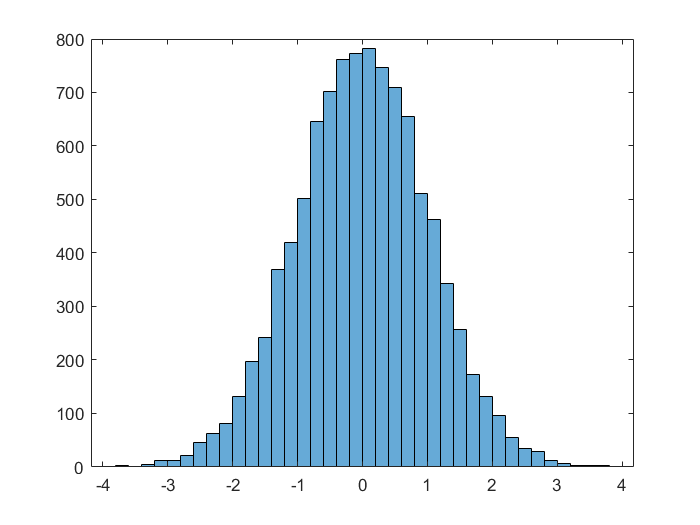

% 标准正态分布
 
x= randn(100);
y = x(:);  % 讲x按列拉长为一个列向量
histogram(y);

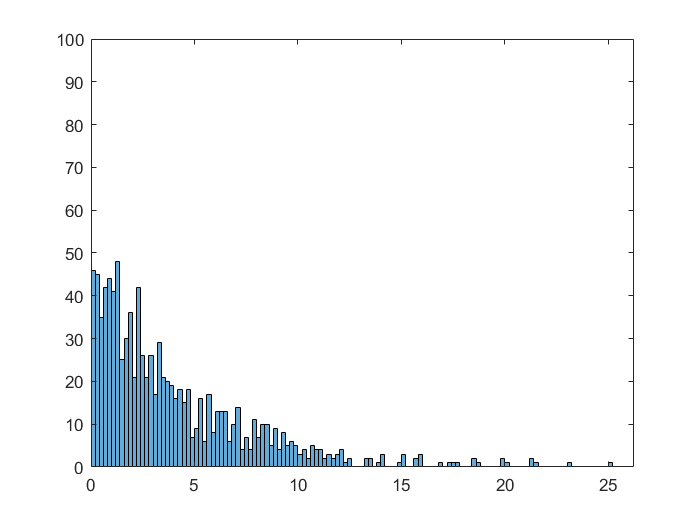

% 指数分布
 
%设置指数分布参数 
mu = 4;

% 产生len个随机数
len = 5;
y1 = exprnd(mu,[1 len]);

% 产生p行Q列矩阵
P = 3;
Q = 4;
y2 = exprnd(mu,P,Q);

%显示指数分布的柱状图
M = 1000;
y3 = exprnd(mu, [1, M]);
figure(1);
t = 0:0.2:max(y3);
histogram(y3,t);
axis([0 max(y3) 0 100]);

% 正态分布
%正态分布常用的指令有：normpdf，normfit，norminv
%normplot，normspec,normstat

mu0 = log(1000);
sigma0 = 1;
% 产生len个随机数
len = 5;
y1 = normrnd(mu0,sigma0,[1 len])

y1 =     7.2589    6.1884    5.7504    7.0718    7.8656


%产生P行Q列的矩阵
p = 3;Q = 4;
y2 = normrnd(mu0,sigma0,[P Q])

y2 =     6.4089    8.1101    8.7095    5.3891
    6.9140    6.8813    6.6991    6.1945
    6.5993    5.4249    6.6920    6.3565


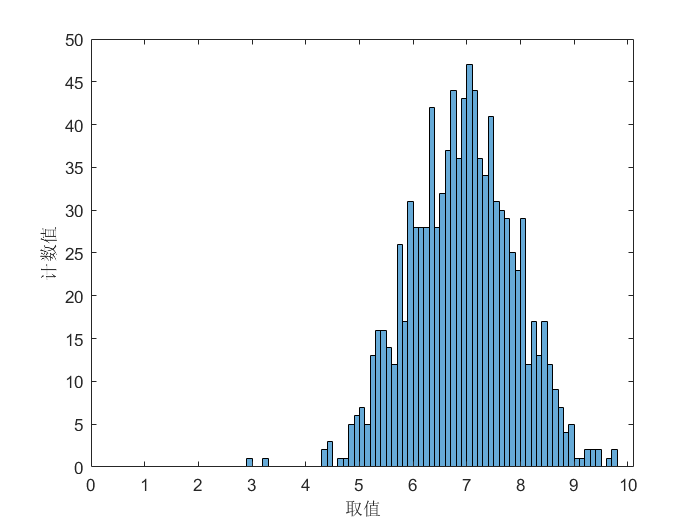


%显示分布的柱状图
M = 1000;
y3 = normrnd(mu0,sigma0,[1 M]);

figure;
t = 0:0.1:max(y3);
histogram(y3,t);
axis([0 max(y3) 0 50]);
xlabel("取值");ylabel("计数值");

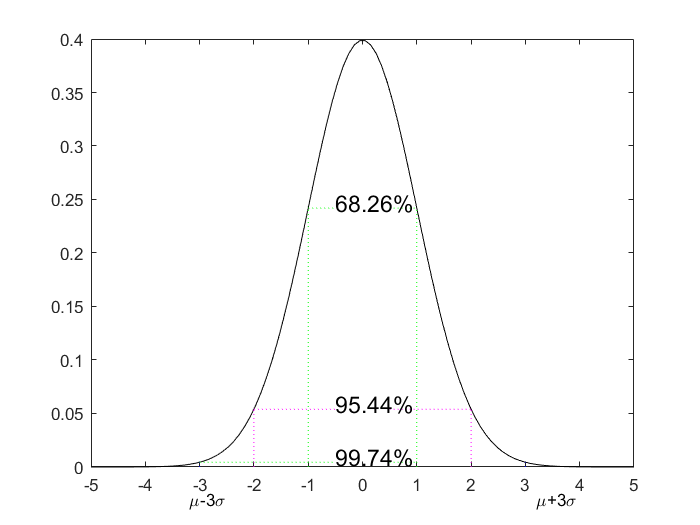

clear all;
%正态分布3sigma准则
%标准正态分布下的面积
X = linspace(-5, 5, 100);
Y = normpdf(X,0,1);
yy = normpdf([-3,-2,-1,0,1,2,3],0,1);
%plot(X,Y,'K-',[0,0],[0,yy(4),'c-.'])
plot(X,Y,'K-');
hold on;
plot([-2,-2],[0,yy(2)],'m:',[2,2],[0,yy(6)],'m:',...
    [-2,-0.5],[yy(6),yy(6)],'m:',[0.5,2],[yy(6),yy(6)],'m:');

plot([-1,-1],[0,yy(3)],'g:',[1,1],[0,yy(5)],'g:',...
    [-1,-0.5],[yy(5),yy(5)],'g:',[0.5,1],[yy(5),yy(5)],'g:');
plot([-3,-3],[0,yy(1)],'b:',[3,3],[0,yy(7)],'b:',...
    [-3,-0.5],[yy(1),yy(1)],'g:',[0.5,1],[yy(7),yy(7)],'g:');
hold off;
text(-0.5,yy(6)+0.005,'\fontsize{14}95.44%');
text(-0.5,yy(5)+0.005,'\fontsize{14}68.26%');
text(-0.5,yy(7)+0.005,'\fontsize{14}99.74%');

text(-3.2,-0.03,'\fontsize{10}\mu-3\sigma');
text(3.2,-0.03,'\fontsize{10}\mu+3\sigma');

%均匀分布
%此处省略


%二次项分布：此处省略

%卡方分布
%中心卡方分布
%卡方分布的分布函数：chi2cdf;分布函数的反函数chi2inv;概率密度函数：chi2pdf
%随机数发生函数chi2rnd；期望及方差计算函数：chi2stat
%分别绘制自由度为3，5，15的卡方分布概率密度函数曲线
clear all；
x = 0:0.1:30;  %给出x的取值
y1 = chi2pdf(x,3) %计算对应的自由度为1的概率密度函数

y1 =          0    0.1200    0.1614    0.1881    0.2066    0.2197    0.2289    0.2352    0.2392    0.2413    0.2420    0.2414    0.2398    0.2375    0.2344    0.2308    0.2267    0.2223    0.2176    0.2127    0.2076    0.2023    0.1970    0.1916    0.1861    0.1807    0.1753    0.1699    0.1646    0.1594    0.1542    0.1491    0.1441    0.1392    0.1344    0.1297    0.1251    0.1207    0.1163    0.1121    0.1080    0.1040    0.1001    0.0964    0.0927    0.0892    0.0858    0.0825    0.0793    0.0762


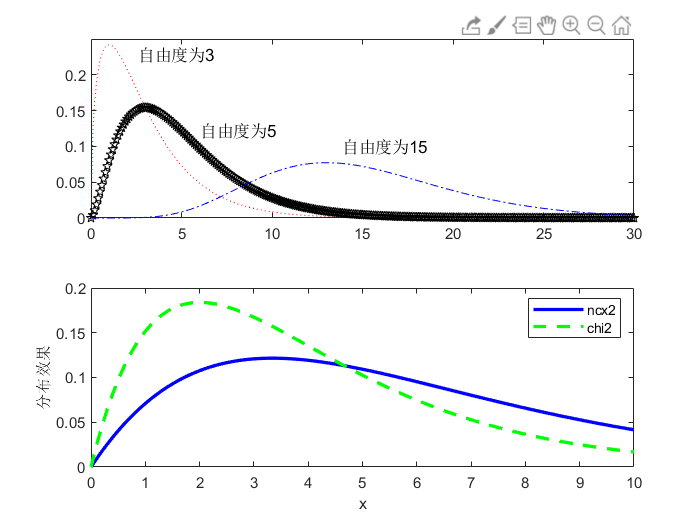

subplot(2,1,1)
plot(x,y1,'r:')
hold on;
y2 = chi2pdf(x,5);
plot(x,y2,'kp');
y3 = chi2pdf(x,15);
plot(x,y3,'b-.');
gtext('自由度为3');
gtext('自由度为5');
gtext('自由度为15');
axis([0 30 0 0.25]);
[m,v] = chi2stat(15);%计算自由度15时候的均值与方差

subplot(2,1,2)
%非中心的卡方分布
%对于非中心的卡方分布有以下指令：
%ncx2pdf；ncx2pdf；ncx2inv，ncx2rnd,ncx2stat
%下面实现非中心和中心的卡方分布
x = (0:0.1:10);
ncx2 = ncx2pdf(x,4,2);
chi2 = chi2pdf(x,4);
plot(x,ncx2,'b-','LineWidth',2);
hold on;
plot(x,chi2,'g--','LineWidth',2);
xlabel('x');ylabel('分布效果');
legend('ncx2','chi2');

% F分布

% t分布

% 几何分布

% 超几何分布

% Beta分布

% 泊松分布

% 瑞利分布

% 多元随机分布
 
clear all;
n = 100;  %多项式分布参数n
p = [0.2,0.3,0.5];  %多项式分布参数p
%调用mnrnd函数生成10组3项分布随机数
r = mnrnd(n,p,10)

r =     18    30    52
    19    31    50
    16    30    54
    18    24    58
    21    29    50
    24    28    48
    17    24    59
    23    27    50
    16    34    50
    22    32    46


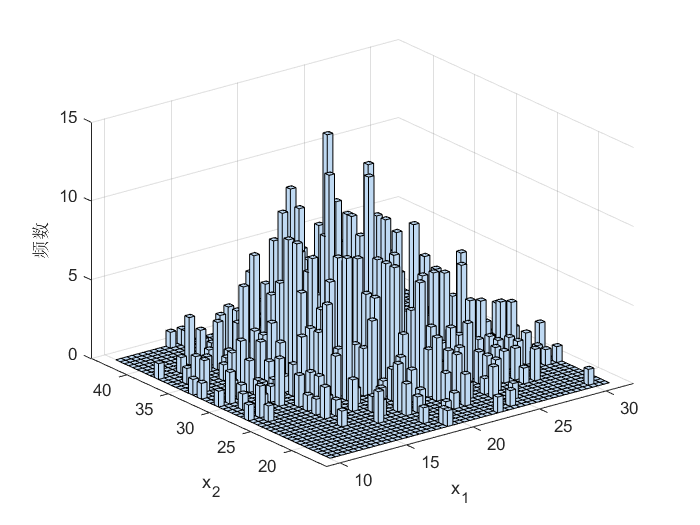

%调用mnrnd函数生成10000组3项分布随机数
r = mnrnd(n,p,1000);
hist3(r(:,1:2),[50,50]);%绘制前两维分布直方图
xlabel('x_1'); ylabel('x_2');zlabel('频数');

set(gcf,'color','w');

% 二元正态分布
mu =[10,20];   %二元正态分布的均值
sigma = [1 3;3,16];  %二元正态分布的协方差

% 调用mvnrnd函数生成10组二元正态分布的随机数
y = mvnrnd(mu,sigma,10)

y =     9.3884   15.0239
    8.4412   15.2000
    8.9744   15.5278
   10.6859   21.8216
   10.0026   22.3571
   12.1314   29.1143
   11.6086   22.3425
    9.9052   15.6486
   10.3062   17.7073
    8.8362   11.1037


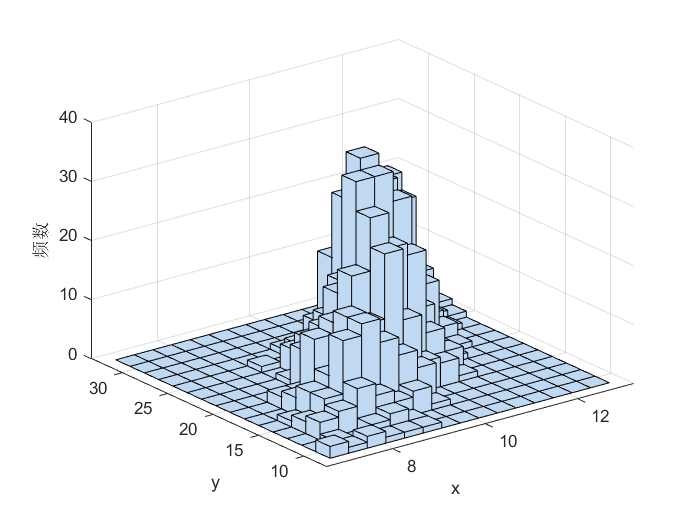

% 调用mvnrnd函数生成1000组二元正态分布的随机数
y = mvnrnd(mu,sigma,1000);
hist3(y,[15,15]);
xlabel('x');ylabel('y');zlabel('频数');